clc
clear all
close all

[inp_aud,fs] =audioread('input_audio.wav'); 
t=length(inp_aud)/fs; %%% signal duration
fprintf('Signal duration= %f secs\n',t);

Signal duration= 4.210000 secs


fprintf('Sampling frequency= %d Hz\n',fs);

Sampling frequency= 48000 Hz



p=10;  %filter order
fprintf('Filter order: %d\n',p);

Filter order: 10


play_snd=@soundsc;


%%encoding:::

fr=0.03;    %frame size=30ms
fprintf('Frame size= %d ms\n',fr*1000);

Frame size= 30 ms


frm_len=fs*fr; %no of samples in a frame
n=frm_len-1;




 
%% voiced/unvoiced & pitch
 for frm=1:frm_len:(length(inp_aud)-frm_len)
    y=inp_aud(frm:frm+n);
    autocor=xcorr(y);
    [pk,ind]=findpeaks(autocor);
    pitch_freq(frm:(frm+n))=mean(fs./diff(ind));
    pitch_per(frm:(frm+n))=1/mean(fs./diff(ind));

     if(80<=pitch_freq(frm:(frm+n)) & 350>=pitch_freq(frm:(frm+n)))
        v_uv(frm:(frm+n))=1;    % voiced/unvoiced count
     else
         v_uv(frm:(frm+n))=0;
     end
 end

 
 
 %Coefficients and gain::(levinson-durbin method)
for frm=1:frm_len:(length(inp_aud)-frm_len)
    y=inp_aud(frm:frm+n);    
    coef_init=zeros(p+1);
    autocor=xcorr(y);
    R=autocor(((length(autocor)+1)./2):length(autocor));
    
    ep(1)=R(1);          
    for j=2:p+1
        tot=0;               
        for i=2:(j-1)
            tot=tot+coef_init(i,(j-1)).*R(j-i+1);
        end
        T(j)=(R(j)+tot)./ep(j-1);
        ep(j)=ep(j-1).*(1-(T(j)).^2);

        coef_init(j,j)= -T(j);
        coef_init(1,j)=1;
        for i=2:(j-1)
            coef_init(i,j)=coef_init(i,(j-1))-T(j).*coef_init((j-i+1),(j-1));
        end
    end

    q=coef_init((1:j),j)';       
    num_co=length(q);
    y_estm=filter([0 -q(2:end)],1,y);    
    e=y-y_estm;  %% errors

    A(frm:(frm+num_co-1))=q; 
    
    %% gain::
    if(v_uv(frm)==0)
        gain(frm)=sqrt(sum(e(1:length(e)).^2)/length(e));%%sqrt(MSE)
    else      
        denom=(floor(length(e)/pitch_per(frm))*pitch_per(frm));
        gain(frm)=sqrt(pitch_per(frm).*sum(e(1:denom).^2)/denom);
    end

end


%%% encoding ends...

%decoding::
for frm=1:frm_len:(length(gain))
    if(v_uv(frm)==1) %voiced 
            for h=1:frm_len
                if(h/pitch_per(frm)==floor(h/pitch_per(frm)))
                    pulse_tr(h)=1;
                else pulse_tr(h)=0;
                end
            end            

    w=filter(1,[1 A((frm+1):(frm+1+p-1))],pulse_tr*gain(frm));

    else %unvoiced
        wn=randn(1,frm_len);
        w=filter(1,[1 A((frm+1):(frm+1+p-1))],wn*gain(frm));
    end
    
    dec_aud(frm:frm+frm_len-1)=w;
end
    
%%decoding ends....   
    
  
fprintf('Original sound Playing...\n');

Original sound Playing...


play_snd(inp_aud,fs);
pause(round(t)+5);

fprintf('Decoded sound playing...\n');

Decoded sound playing...


play_snd(dec_aud,fs);

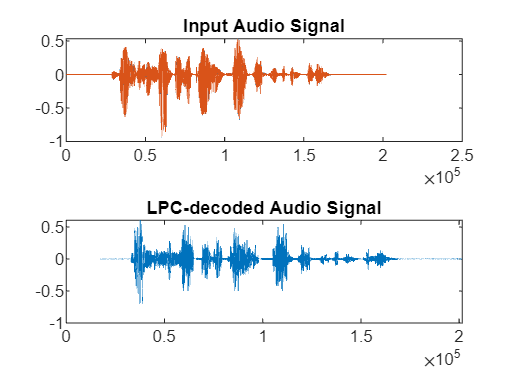


subplot(2,1,1);
plot(inp_aud);
title('Input Audio Signal');
subplot(2,1,2);
plot(dec_aud);
title('LPC-decoded Audio Signal');